# Linear Transormations Examples

[Link to lecture notes](https://jonshiach.github.io/graphics-book/files/2.0_Transformations.html)

### Example 19 - Transformation matrix

T = @(v) [ 3 * v(1) + v(2) ; 
           v(1) + 2 * v(2) ];

A = sym([T([1 ; 0]), T([0 ; 1])])

$$A = \left(\begin{array}{cc} 3 & 1\\ 1 & 2 \end{array}\right)$$

A * [1 ; 1]

$$ans = \left(\begin{array}{c} 4\\ 3 \end{array}\right)$$

### Example 20 - Transformation matrix from a set of images

u1 = [1 ; 1];
u2 = [1 ; 2];
Tu1 = [4 ; 3];
Tu2 = [5 ; 5];

A = sym([Tu1, Tu2] * inv([u1, u2]))

$$A = \left(\begin{array}{cc} 3 & 1\\ 1 & 2 \end{array}\right)$$

### Example 21 - Inverse linear transformations

T = @(v) [ 3 * v(1) + v(2) ; 
           v(1) + 2 * v(2) ];

A = sym([T([1 ; 0]), T([0 ; 1])])

$$A = \left(\begin{array}{cc} 3 & 1\\ 1 & 2 \end{array}\right)$$

invA = inv(A)

$$invA = \left(\begin{array}{cc} \frac{2}{5} & -\frac{1}{5}\\ -\frac{1}{5} & \frac{3}{5} \end{array}\right)$$

invA * [4 ; 3]

$$ans = \left(\begin{array}{c} 1\\ 1 \end{array}\right)$$

### Example 22 - Composite linear transformations

(i)

T = @(v) [ 2 * v(1) + 4 * v(2) ; 
          -v(1) + 3 * v(2) ; 
          v(1) + 2 * v(2) ];
S = @(v) [ 2 * v(1) + v(2) - v(3) ; 
           3 * v(1) + v(3) ; 
           v(2) - 2 * v(3) ];

syms x y z
u = [x ; y ; z];
S(T(u))

$$ans = \left(\begin{array}{c} 2\,x+9\,y\\ 7\,x+14\,y\\ -3\,x-y \end{array}\right)$$

(ii)

e1 = [1 ; 0];
e2 = [0 ; 1];
A = sym([T(e1), T(e2)])

$$A = \left(\begin{array}{cc} 2 & 4\\ -1 & 3\\ 1 & 2 \end{array}\right)$$

e1 = [1 ; 0 ; 0];
e2 = [0 ; 1 ; 0];
e3 = [0 ; 0 ; 1];
B = sym([S(e1), S(e2), S(e3)])

$$B = \left(\begin{array}{ccc} 2 & 1 & -1\\ 3 & 0 & 1\\ 0 & 1 & -2 \end{array}\right)$$

C = B * A

$$C = \left(\begin{array}{cc} 2 & 9\\ 7 & 14\\ -3 & -1 \end{array}\right)$$

(iii)

syms x y
u = [x ; y];
C * u

$$ans = \left(\begin{array}{c} 2\,x+9\,y\\ 7\,x+14\,y\\ -3\,x-y \end{array}\right)$$

### Translation

p1 = [1 ; 0 ; 1];
p2 = [3 ; 0 ; 1];
p3 = [2 ; 0 ; 3];
t = [3 ; 0 ; 1];

P = sym([p1, p2, p3]);
P(4,:) = ones(1,size(P,2))

$$P = \left(\begin{array}{ccc} 1 & 3 & 2\\ 0 & 0 & 0\\ 1 & 1 & 3\\ 1 & 1 & 1 \end{array}\right)$$

T = @(t) [ 1, 0, 0, t(1) ; 
           0, 1, 0, t(2) ; 
           0, 0, 1, t(3) ; 
           0, 0, 0, 1 ];

sym(T(t))

$$ans = \left(\begin{array}{cccc} 1 & 0 & 0 & 3\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 1\\ 0 & 0 & 0 & 1 \end{array}\right)$$

P1 = T(t) * P

$$P1 = \left(\begin{array}{ccc} 4 & 6 & 5\\ 0 & 0 & 0\\ 2 & 2 & 4\\ 1 & 1 & 1 \end{array}\right)$$

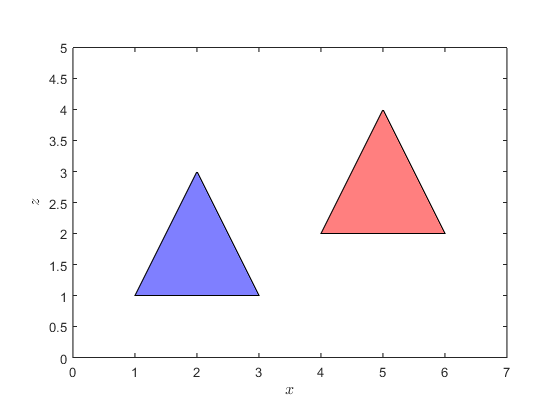

P = double(P);
P1 = double(P1);

figure
patch(P(1,:), P(3,:), 'b', FaceAlpha=0.5)
patch(P1(1,:), P1(3,:), 'r', FaceAlpha=0.5)
axis equal
axis([0, 7, 0, 5])
xlabel("$x$", FontSize=12, Interpreter="latex")
ylabel("$z$", FontSize=12, Interpreter="latex")
box
exportgraphics(gcf,'../images/translation_example.png','Resolution',300)

### Example 24 - Scaling

p1 = [1 ; 0 ; 1];
p2 = [3 ; 0 ; 1];
p3 = [2 ; 0 ; 3];
s = [3 ; 1 ; 2];

P = sym([p1, p2, p3]);
P(4,:) = ones(1,size(P,2))

$$P = \left(\begin{array}{ccc} 1 & 3 & 2\\ 0 & 0 & 0\\ 1 & 1 & 3\\ 1 & 1 & 1 \end{array}\right)$$

S = @(s) [ s(1), 0, 0, 0 ; 
           0, s(2), 0, 0 ; 
           0, 0, s(3), 0 ; 
           0, 0, 0, 1 ];
sym(S(s))

$$ans = \left(\begin{array}{cccc} 3 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 2 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

P1 = S(s) * P

$$P1 = \left(\begin{array}{ccc} 3 & 9 & 6\\ 0 & 0 & 0\\ 2 & 2 & 6\\ 1 & 1 & 1 \end{array}\right)$$

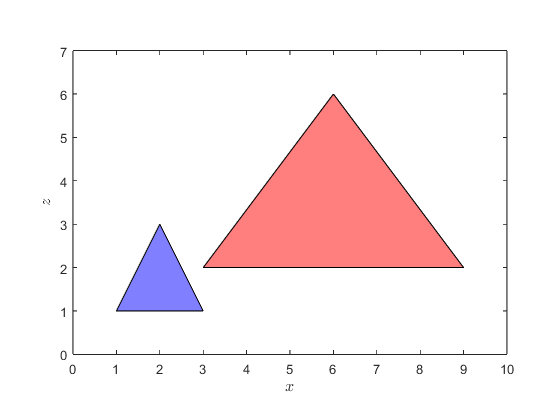

P = double(P);
P1 = double(P1);

figure
patch(P(1,:), P(3,:), 'b', FaceAlpha=0.5)
patch(P1(1,:), P1(3,:), 'r', FaceAlpha=0.5)
axis equal 
axis([0, 10, 0, 7])
xlabel("$x$", FontSize=12, Interpreter="latex")
ylabel("$z$", FontSize=12, Interpreter="latex")
box
exportgraphics(gcf,'../images/scaling_example.png','Resolution',300)

### Example 25 - Scaling about centre

p1 = [1 ; 0 ; 1];
p2 = [3 ; 0 ; 1];
p3 = [2 ; 0 ; 3];
s = [3 ; 1 ; 2];

P = sym([p1, p2, p3]);
P(4,:) = ones(1,size(P,2))

$$P = \left(\begin{array}{ccc} 1 & 3 & 2\\ 0 & 0 & 0\\ 1 & 1 & 3\\ 1 & 1 & 1 \end{array}\right)$$

s = sym([2 ; 2 ; 2]);
c = sym(1/3 * [p1 + p2 + p3])

$$c = \left(\begin{array}{c} 2\\ 0\\ \frac{5}{3} \end{array}\right)$$

T = @(t) [ 1, 0, 0, t(1) ; 
           0, 1, 0, t(2) ; 
           0, 0, 1, t(3) ; 
           0, 0, 0, 1 ];

S = @(s) [ s(1), 0, 0, 0 ; 
           0, s(2), 0, 0 ; 
           0, 0, s(3), 0 ; 
           0, 0, 0, 1 ];

T(-c)

$$ans = \left(\begin{array}{cccc} 1 & 0 & 0 & -2\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & -\frac{5}{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

S(s)

$$ans = \left(\begin{array}{cccc} 2 & 0 & 0 & 0\\ 0 & 2 & 0 & 0\\ 0 & 0 & 2 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T(c)

$$ans = \left(\begin{array}{cccc} 1 & 0 & 0 & 2\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & \frac{5}{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A = T(c) * S(s) * T(-c)

$$A = \left(\begin{array}{cccc} 2 & 0 & 0 & -2\\ 0 & 2 & 0 & 0\\ 0 & 0 & 2 & -\frac{5}{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

P1 = A * P

$$P1 = \left(\begin{array}{ccc} 0 & 4 & 2\\ 0 & 0 & 0\\ \frac{1}{3} & \frac{1}{3} & \frac{13}{3}\\ 1 & 1 & 1 \end{array}\right)$$

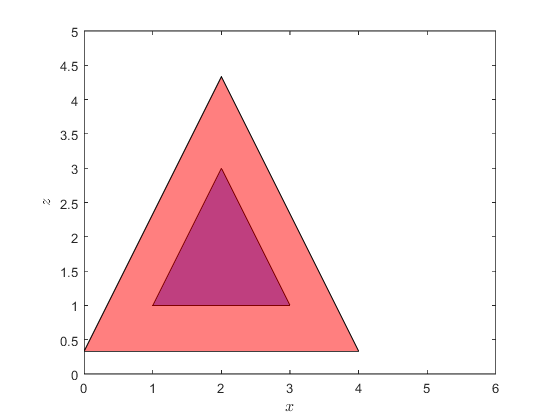

P = double(P);
P1 = double(P1);

figure
patch(P(1,:), P(3,:), 'b', FaceAlpha=0.5)
patch(P1(1,:), P1(3,:), 'r', FaceAlpha=0.5)
axis equal
axis([0, 6, 0, 5])
xlabel("$x$", FontSize=12, Interpreter="latex")
ylabel("$z$", FontSize=12, Interpreter="latex")
box
exportgraphics(gcf,'../images/scaling_about_centre_example.png','Resolution',300)

### Example 26 - Rotation

p1 = [4 ; 1 ; 2];
p2 = [6 ; 1 ; 2];
p3 = [5 ; 3 ; 2];
theta = pi / 4;

P = sym([p1, p2, p3]);
P(4,:) = ones(1,size(P,2))

$$P = \left(\begin{array}{ccc} 4 & 6 & 5\\ 1 & 1 & 3\\ 2 & 2 & 2\\ 1 & 1 & 1 \end{array}\right)$$

Rz = @(theta) [ cos(theta), -sin(theta), 0, 0 ; 
                sin(theta), cos(theta), 0, 0 ;
                0, 0, 1, 0 ;
                0, 0, 0, 1 ];

sym(Rz(theta))

$$ans = \left(\begin{array}{cccc} \frac{\sqrt{2}}{2} & -\frac{\sqrt{2}}{2} & 0 & 0\\ \frac{\sqrt{2}}{2} & \frac{\sqrt{2}}{2} & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

P1 = Rz(theta) * P

$$P1 = \left(\begin{array}{ccc} \frac{3\,\sqrt{2}}{2} & \frac{5\,\sqrt{2}}{2} & \sqrt{2}\\ \frac{5\,\sqrt{2}}{2} & \frac{7\,\sqrt{2}}{2} & 4\,\sqrt{2}\\ 2 & 2 & 2\\ 1 & 1 & 1 \end{array}\right)$$

P = double(P);
P1 = double(P1)

P1 =     2.1213    3.5355    1.4142
    3.5355    4.9497    5.6569
    2.0000    2.0000    2.0000
    1.0000    1.0000    1.0000


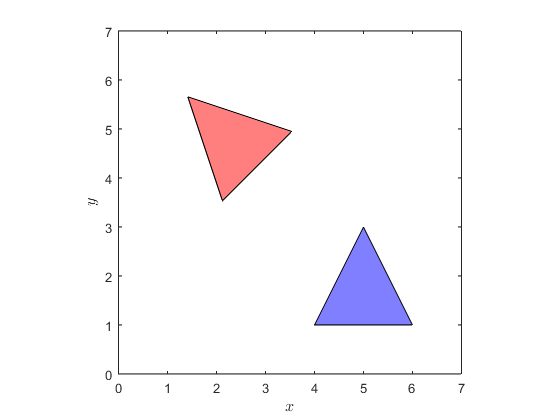

figure
patch(P(1,:), P(2,:), 'b', FaceAlpha=0.5)
patch(P1(1,:), P1(2,:), 'r', FaceAlpha=0.5)
axis equal
axis([0, 7, 0, 7])
xlabel("$x$", FontSize=12, Interpreter="latex")
ylabel("$y$", FontSize=12, Interpreter="latex")
box
exportgraphics(gcf,'../images/rotation_example.png','Resolution',300)

### Example 27 - Rotation about centre

p1 = [4 ; 1 ; 2];
p2 = [6 ; 1 ; 2];
p3 = [5 ; 3 ; 2];
theta = pi / 4;

P = sym([p1, p2, p3]);
P(4,:) = ones(1,size(P,2))

$$P = \left(\begin{array}{ccc} 4 & 6 & 5\\ 1 & 1 & 3\\ 2 & 2 & 2\\ 1 & 1 & 1 \end{array}\right)$$

c = sym(1/3 * [p1 + p2 + p3])

$$c = \left(\begin{array}{c} 5\\ \frac{5}{3}\\ 2 \end{array}\right)$$

T = @(t) [ 1, 0, 0, t(1) ; 
           0, 1, 0, t(2) ; 
           0, 0, 1, t(3) ; 
           0, 0, 0, 1 ];

S = @(s) [ s(1), 0, 0, 0 ; 
           0, s(2), 0, 0 ; 
           0, 0, s(3), 0 ; 
           0, 0, 0, 1 ];

Rz = @(theta) [ cos(theta), -sin(theta), 0, 0 ;  
                sin(theta), cos(theta), 0, 0 ;
                0, 0, 1, 0 ;
                0, 0, 0, 1 ];

T(-c)

$$ans = \left(\begin{array}{cccc} 1 & 0 & 0 & -5\\ 0 & 1 & 0 & -\frac{5}{3}\\ 0 & 0 & 1 & -2\\ 0 & 0 & 0 & 1 \end{array}\right)$$

sym(Rz(theta))

$$ans = \left(\begin{array}{cccc} \frac{\sqrt{2}}{2} & -\frac{\sqrt{2}}{2} & 0 & 0\\ \frac{\sqrt{2}}{2} & \frac{\sqrt{2}}{2} & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T(c)

$$ans = \left(\begin{array}{cccc} 1 & 0 & 0 & 5\\ 0 & 1 & 0 & \frac{5}{3}\\ 0 & 0 & 1 & 2\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A = T(c) * Rz(theta) * T(-c)

$$A = \left(\begin{array}{cccc} \frac{\sqrt{2}}{2} & -\frac{\sqrt{2}}{2} & 0 & 5-\frac{5\,\sqrt{2}}{3}\\ \frac{\sqrt{2}}{2} & \frac{\sqrt{2}}{2} & 0 & \frac{5}{3}-\frac{10\,\sqrt{2}}{3}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

P1 = A * P

$$P1 = \left(\begin{array}{ccc} 5-\frac{\sqrt{2}}{6} & \frac{5\,\sqrt{2}}{6}+5 & 5-\frac{2\,\sqrt{2}}{3}\\ \frac{5}{3}-\frac{5\,\sqrt{2}}{6} & \frac{\sqrt{2}}{6}+\frac{5}{3} & \frac{2\,\sqrt{2}}{3}+\frac{5}{3}\\ 2 & 2 & 2\\ 1 & 1 & 1 \end{array}\right)$$

P = double(P);
P1 = double(P1)

P1 =     4.7643    6.1785    4.0572
    0.4882    1.9024    2.6095
    2.0000    2.0000    2.0000
    1.0000    1.0000    1.0000


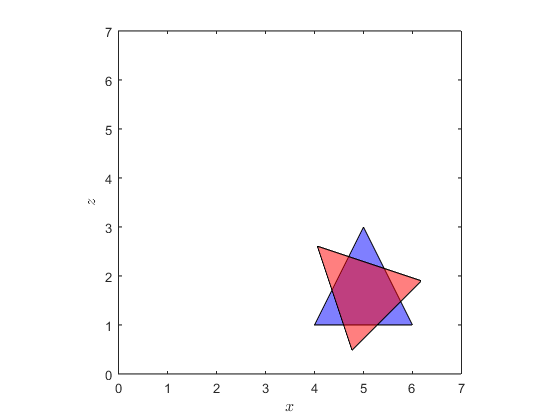

figure
patch(P(1,:), P(2,:), 'b', FaceAlpha=0.5)
patch(P1(1,:), P1(2,:), 'r', FaceAlpha=0.5)
axis equal
axis([0, 7, 0, 7])
xlabel("$x$", FontSize=12, Interpreter="latex")
ylabel("$z$", FontSize=12, Interpreter="latex")
box
exportgraphics(gcf,'../images/rotation_about_centre_example.png','Resolution',300)

### Example 28 - Rotation about a line

c = [10 ; 5 ; 50];
d = [2 ; -1 ; -3];
theta = pi / 6;

T = @(t) [ 1, 0, 0, t(1) ; 
           0, 1, 0, t(2) ; 
           0, 0, 1, t(3) ; 
           0, 0, 0, 1 ];

Rx = @(theta) [ 1, 0, 0, 0 ;
                0, cos(theta), -sin(theta), 0 ;
                0, sin(theta), cos(theta), 0 ;
                0, 0, 0, 1 ];

sym(T(-c))

$$ans = \left(\begin{array}{cccc} 1 & 0 & 0 & -10\\ 0 & 1 & 0 & -5\\ 0 & 0 & 1 & -50\\ 0 & 0 & 0 & 1 \end{array}\right)$$

d1 = sym(sqrt(d(1)^2 + d(2)^2))

$$d1 = \sqrt{5}$$

c = d(1) / d1;
s = abs(d(2)) / d1;
Rz = [c, -s, 0, 0 ; 
      s,  c, 0, 0 ; 
      0,  0, 1, 0 ;
      0,  0, 0, 1 ]

$$Rz = \left(\begin{array}{cccc} \frac{2\,\sqrt{5}}{5} & -\frac{\sqrt{5}}{5} & 0 & 0\\ \frac{\sqrt{5}}{5} & \frac{2\,\sqrt{5}}{5} & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Rz * [d ; 1]

$$ans = \left(\begin{array}{c} \sqrt{5}\\ 0\\ -3\\ 1 \end{array}\right)$$

magd = sym(norm(d))

$$magd = \sqrt{14}$$

c = d1 / magd;
s = abs(d(3)) / magd;
Ry = [ c, 0, -s, 0 ;
       0, 1,  0, 0 ;
       s, 0,  c, 0 ;
       0, 0,  0, 1 ]

$$Ry = \left(\begin{array}{cccc} \frac{\sqrt{5}\,\sqrt{14}}{14} & 0 & -\frac{3\,\sqrt{14}}{14} & 0\\ 0 & 1 & 0 & 0\\ \frac{3\,\sqrt{14}}{14} & 0 & \frac{\sqrt{5}\,\sqrt{14}}{14} & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Ry * Rz * [d ; 1]

$$ans = \left(\begin{array}{c} \sqrt{14}\\ 0\\ 0\\ 1 \end{array}\right)$$

sym(Rx(theta))

$$ans = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & \frac{\sqrt{3}}{2} & -\frac{1}{2} & 0\\ 0 & \frac{1}{2} & \frac{\sqrt{3}}{2} & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$ans = \left(\begin{array}{cccc} \frac{2\,\sqrt{5}}{5} & \frac{\sqrt{5}}{5} & 0 & 0\\ -\frac{\sqrt{5}}{5} & \frac{2\,\sqrt{5}}{5} & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$ans = \left(\begin{array}{cccc} \frac{\sqrt{5}\,\sqrt{14}}{14} & 0 & \frac{3\,\sqrt{14}}{14} & 0\\ 0 & 1 & 0 & 0\\ -\frac{3\,\sqrt{14}}{14} & 0 & \frac{\sqrt{5}\,\sqrt{14}}{14} & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Index exceeds the number of array elements. Index must not exceed 1.

Error in indexing (line 1075)
            R_tilde = builtin('subsref',L_tilde,Idx);

Error in Linear_transformations_examples (line 195)
           0, 1, 0, t(2) ; 